# Application Problems

## Problem 2.6 (First-order approximation of functions) 

### Part a)

syms x y
f1(x,y) = 2.*x + 3.*y + 1
f2(x,y) = x.^2 + y.^2 - x.*y -5
f3(x,y) = (x-5).*cos(y-5) - (y-5).*sin(x-5)
v = [x,y];
F1 = gradient(f1,v)
F2 = gradient(f2,v)
F3 = gradient(f3,v)

### Part b)

[X,Y] = meshgrid(-2:0.5:3.5,-2:0.5:3.5);
f_1 = 2.*X + 3.*Y + 1;
fcontour(f1, [-2 3.5])
[U,V] = gradient(f_1,0.2,0.2);
F1(1,0)'
hold on
quiver(X,Y,U,V);
hold off
[X,Y] = meshgrid(-2:0.15:3.5,-2:0.15:3.5);
f_2 = X.^2 + Y.^2 - X.*Y -5;
fcontour(f2, [-2 3.5])
[U,V] = gradient(f_2,0.2,0.2);
F2(1,0)'
hold on
quiver(X,Y,U,V);
hold off
f_3 = (X-5).*cos(Y-5) - (Y-5)*sin(X-5);
fcontour(f3, [-2 3.5])
[U,V] = gradient(f_3,0.2,0.2);
F3(1,0)'
hold on
quiver(X,Y,U,V);
hold off

### Part c)

f = @(x,y) 2.*x + 3.*y + 1;
[xx,yy] = meshgrid(-5:0.25:5);
[fx,fy] = gradient(f(xx,yy),0.25);
x0 = 1;
y0 = 0;
t = (xx == x0) & (yy == y0);
indt = find(t);
fx0 = fx(indt);
fy0 = fy(indt);

z = @(x,y) f(x0,y0) + fx0*(x-x0) + fy0*(y-y0);
% Create a 3D surface plot of the original function
figure;
surf(xx,yy,f(xx,yy),'EdgeAlpha',0.7,'FaceAlpha',0.9)
hold on
surf(xx,yy,z(xx,yy))
plot3(1,0,f(1,0),'r*')
xlabel('X');
ylabel('Y');
zlabel('f(X, Y)');
title('Original Function');
f = @(x,y) x.^2 + y.^2 - x.*y -5;
[xx,yy] = meshgrid(-5:0.25:5);
[fx,fy] = gradient(f(xx,yy),0.25);
x0 = 1;
y0 = 0;
t = (xx == x0) & (yy == y0);
indt = find(t);
fx0 = fx(indt);
fy0 = fy(indt);

z = @(x,y) f(x0,y0) + fx0*(x-x0) + fy0*(y-y0);
% Create a 3D surface plot of the original function
figure;
surf(xx,yy,f(xx,yy),'EdgeAlpha',0.7,'FaceAlpha',0.9)
hold on
surf(xx,yy,z(xx,yy))
plot3(1,0,f(1,0),'r*')
xlabel('X');
ylabel('Y');
zlabel('f(X, Y)');
title('Original Function');
f = @(x,y) (x-5).*cos(y-5) - (y-5).*sin(x-5);
[xx,yy] = meshgrid(-5:0.25:5);
[fx,fy] = gradient(f(xx,yy),0.25);
x0 = 1;
y0 = 0;
t = (xx == x0) & (yy == y0);
indt = find(t);
fx0 = fx(indt);
fy0 = fy(indt);

z = @(x,y) f(x0,y0) + fx0*(x-x0) + fy0*(y-y0);
% Create a 3D surface plot of the original function
figure;
surf(xx,yy,f(xx,yy),'EdgeAlpha',0.7,'FaceAlpha',0.9)
hold on
surf(xx,yy,z(xx,yy))
plot3(1,0,f(1,0),'r*')
xlabel('X');
ylabel('Y');
zlabel('f(X, Y)');
title('Original Function');

## Problem 2.7 (Second-order approximation of functions)

### Part a) 

syms x y
f1(x,y) = 2.*x + 3.*y + 1;
f2(x,y) = x.^2 + y.^2 - x.*y -5;
f3(x,y) = (x-5).*cos(y-5) - (y-5).*sin(x-5);
v = [x,y];
F1 = gradient(f1,v);
F2 = gradient(f2,v);
F3 = gradient(f3,v);
Ff1 = double(hessian(f1,[x,y]))

Ff1 =      0     0
     0     0


Ff2 = double(hessian(f2,[x,y]))

Ff2 =      2    -1
    -1     2


Ff3 = hessian(f3,[x,y])

$$Ff3(x, y) = \left(\begin{array}{cc} \sin\left(x-5\right)\,\left(y-5\right) & -\cos\left(x-5\right)-\sin\left(y-5\right)\\ -\cos\left(x-5\right)-\sin\left(y-5\right) & -\cos\left(y-5\right)\,\left(x-5\right) \end{array}\right)$$

[xx,yy] = meshgrid(-2:0.25:3.5);
a = 1;
b = 0;
z1 = taylor(f1,[x,y],[1 0],'Order',3)

$$z1(x, y) = 2\,x+3\,y+1$$

z2 = taylor(f2,[x,y],[1 0],'Order',3)

$$z2(x, y) = 2\,x-y+{\left(x-1\right)}^{2}-y\,\left(x-1\right)+y^{2}-6$$

z3 = taylor(f3,[x,y],[1 0],'Order',3)

$$z3(x, y) = \frac{5\,\sin\left(4\right)\,{\left(x-1\right)}^{2}}{2}-5\,\sin\left(4\right)-4\,\cos\left(5\right)+y\,\left(\sin\left(4\right)-4\,\sin\left(5\right)\right)+2\,y^{2}\,\cos\left(5\right)+\left(5\,\cos\left(4\right)+\cos\left(5\right)\right)\,\left(x-1\right)-y\,\left(\cos\left(4\right)-\sin\left(5\right)\right)\,\left(x-1\right)$$

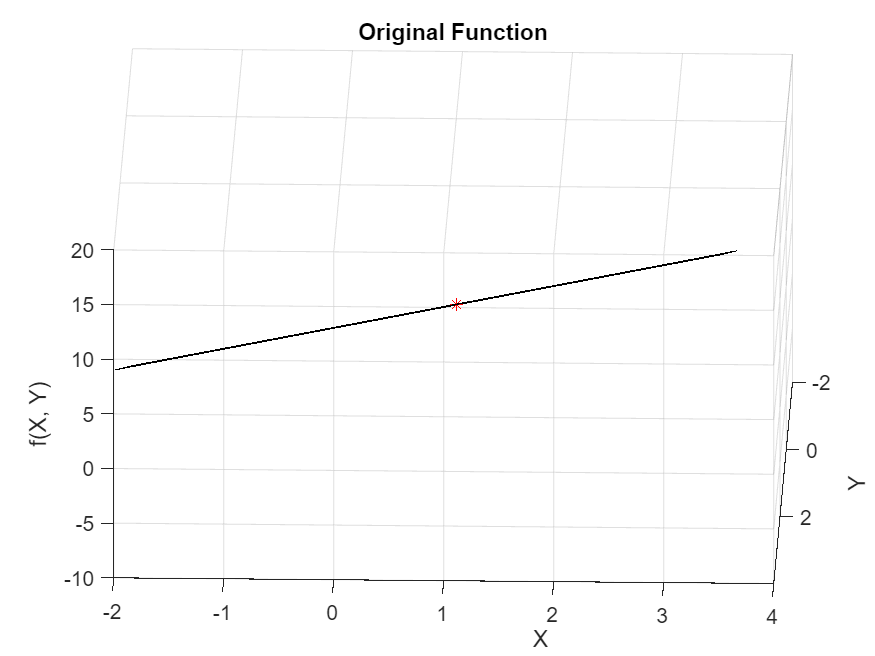

figure;
surf(xx,yy,double(f1(xx,yy)),'EdgeAlpha',0.7,'FaceAlpha',0.9)
hold on
surf(xx,yy,double(z1(xx,yy)))
plot3(a,b,double(f1(a,b)),'r*')
xlabel('X');
ylabel('Y');
zlabel('f(X, Y)');
title('Original Function');

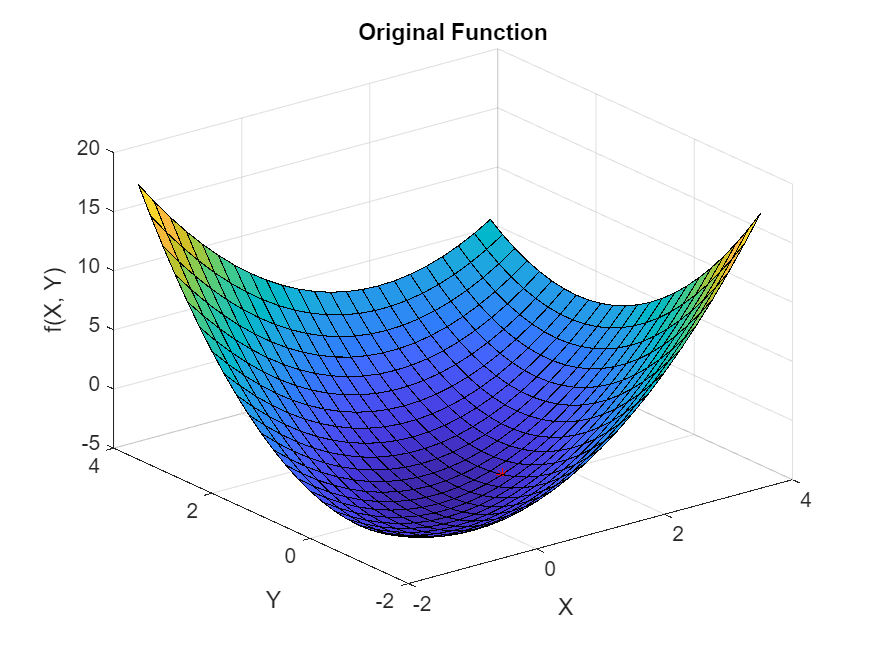

figure;
surf(xx,yy,double(f2(xx,yy)),'EdgeAlpha',0.7,'FaceAlpha',0.9)
hold on
surf(xx,yy,double(z2(xx,yy)))
plot3(a,b,double(f2(a,b)),'r*')
xlabel('X');
ylabel('Y');
zlabel('f(X, Y)');
title('Original Function');

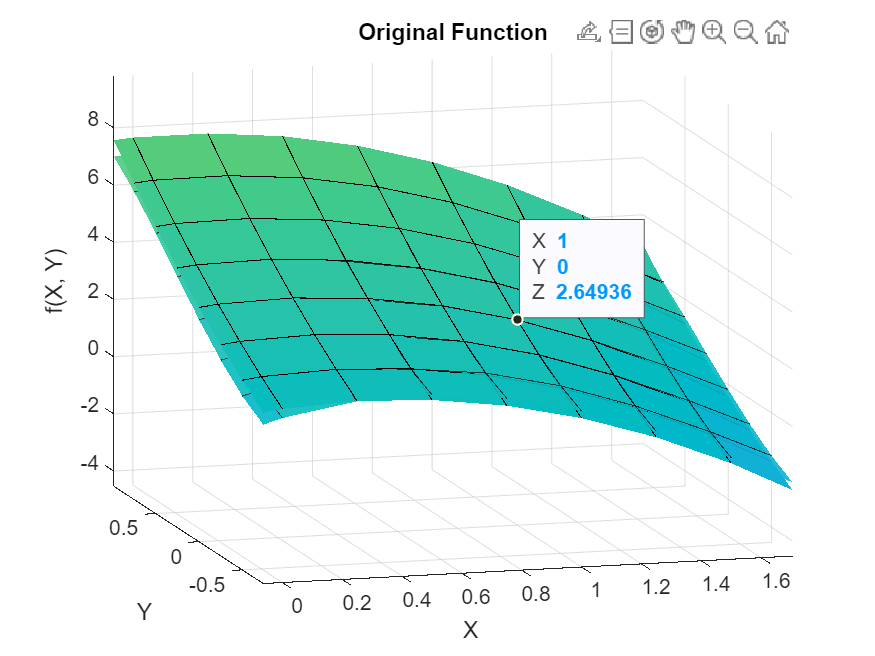

figure;
surf(xx,yy,double(f3(xx,yy)),'EdgeAlpha',0.7,'FaceAlpha',0.9)
hold on
surf(xx,yy,double(z3(xx,yy)))
plot3(a,b,double(f3(a,b)),'r*')
xlabel('X');
ylabel('Y');
zlabel('f(X, Y)');
title('Original Function');